# DTP: Drug Target Prediction

removing trivial associations for all methods with Jaccard

## Initialization 

clear all;

## Read the data

R = load('../data/luo_dataset/mat_drug_protein.txt');
load('../data/luo_dataset/similarities/drug_chem_sim.mat');
load('../data/luo_dataset/similarities/drug_drug_sim.mat');
load('../data/luo_dataset/similarities/drug_side_effect_sim.mat');
load('../data/luo_dataset/similarities/drug_disease_sim.mat');
load('../data/luo_dataset/similarities/prot_disease_sim.mat');
load('../data/luo_dataset/similarities/ppi_sim.mat');
load('../data/luo_dataset/similarities/prot_seq_sim.mat');
chemSim = load('../data/luo_dataset/Similarity_Matrix_Drugs.txt');
protSeqSim = load('../data/luo_dataset/Similarity_Matrix_Proteins.txt');

Similarities for initialisation

indexProt = sum(R,1) > 0;
indexDrug = sum(R,2) > 0;
topN = [10 20 50 100];
nfolds = 10;
chemSim = chemSim(indexDrug,indexDrug);
protSeqSim = protSeqSim(indexProt,indexProt);

R = R(indexDrug,indexProt);
chemSimThresholded_no_diag = chemSimThresholded - chemSimThresholded .*eye(size(chemSimThresholded));
sideEffectThresholded_no_diag = sideEffectThresholded - sideEffectThresholded .*eye(size(sideEffectThresholded));
drugDrugSim_no_diag = drugDrugSim - drugDrugSim .*eye(size(drugDrugSim));
drugDiseaseSimThresholded_no_diag = drugDiseaseSimThresholded - drugDiseaseSimThresholded .*eye(size(drugDiseaseSimThresholded));
protSeqSimThresholded_no_diag = protSeqSimThresholded - protSeqSimThresholded .*eye(size(protSeqSimThresholded));
PPISim_no_diag = PPISim - PPISim .*eye(size(PPISim));
protDiseaseSimThresholded_no_diag = protDiseaseSimThresholded - protDiseaseSimThresholded .*eye(size(protDiseaseSimThresholded));

sideInfoRow_no_diag = {chemSimThresholded_no_diag, sideEffectThresholded_no_diag,...
          drugDrugSim_no_diag, drugDiseaseSimThresholded_no_diag};
sideInfoCol_no_diag = {protSeqSimThresholded_no_diag, PPISim_no_diag, protDiseaseSimThresholded_no_diag};
SIC = [sideInfoCol_no_diag(:)'];
SIR = [sideInfoRow_no_diag(:)'];

Load all the predictions for each method

load('../repository/warm_start_10_CVs/our_method/our_method_predictions_10CV_2026.mat');
load('../repository/warm_start_10_CVs/neoDTI/neoDTI_10_cv_predictions.mat');
load('../repository/warm_start_10_CVs/KGE_NFM/KGE_NFM_10_cv_predictions.mat');
load('../repository/warm_start_10_CVs/DTINet/DTInet_10CV_predictions_10_to_1.mat');
load('../repository/warm_start_10_CVs/hampDTI/hampDTI_predictions.mat');

% our_method_predictions = our_method_predictions_mixed;

Filter Drug Similarity

Calculate the AUC and AUPR with AUCDownSample function for drug similarities < 0.6

drugSim = {chemSim};
drugTresh = {0.60};
for k = 1:10
    AUC_our_method = zeros(nfolds,1);
    AUPR_our_method = zeros(nfolds,1);
    AUC_NeoDTI = zeros(nfolds,1);
    AUPR_NeoDTI = zeros(nfolds,1);
    KGE_NFM_AUC = zeros(nfolds,1);
    KGE_NFM_AUPR = zeros(nfolds,1);
    DTINet_AUC = zeros(nfolds,1);
    DTINet_AUPR = zeros(nfolds,1);
        hampDTI_AUC = zeros(nfolds,1);
        hampDTI_AUPR = zeros(nfolds,1);
    for j = 1:nfolds
        load(['../data/luo_dataset/warm_start_10_CVs/our_method/cv_' int2str(k) '/test' int2str(j) '.mat']);
        filteredTest = filterDTI(test_fold, drugSim,{},drugTresh,{},'drug');
        [AUC_our_method(j), AUPR_our_method(j), ~,~,~,~] = AUCDownSample(filteredTest, our_method_predictions{k}{j});
        [AUC_NeoDTI(j), AUPR_NeoDTI(j), ~,~,~,~] = AUCDownSample(filteredTest, neoDTI_predictions{k}{j});
        [KGE_NFM_AUC(j), KGE_NFM_AUPR(j), ~,~,~,~] = AUCDownSample(filteredTest, KGE_NFM_predictions{k}{j});
        [DTINet_AUC(j), DTINet_AUPR(j), ~,~,~,~] = AUCDownSample(filteredTest, DTINet_predictions_10_1{k}{j});
            [hampDTI_AUC(j), hampDTI_AUPR(j), ~,~,~,~] = AUCDownSample(filteredTest, hampDTI_predictions{k}{j});
    end
    our_method_remove_drug_sim{k} = {AUC_our_method,AUPR_our_method};
    NeoDTI_remove_drug_sim{k} = {AUC_NeoDTI,AUPR_NeoDTI};
    KGE_NFM_remove_drug_sim{k} = {KGE_NFM_AUC,KGE_NFM_AUPR};
    DTINet_remove_drug_sim{k} = {DTINet_AUC,DTINet_AUPR};
    hampDTI_remove_drug_sim{k} = {hampDTI_AUC,hampDTI_AUPR};
end


nfolds = 10;
NeoDTI_AUC = zeros(nfolds,1);
NeoDTI_AUPR = zeros(nfolds,1);
our_method_AUC = zeros(nfolds,1);
our_method_AUPR = zeros(nfolds,1);
KGE_NFM_AUC = zeros(nfolds,1);
KGE_NFM_AUPR = zeros(nfolds,1);
DTINet_all_AUC = zeros(nfolds,1);
DTINet_all_AUPR = zeros(nfolds,1);
hampDTI_all_AUC = zeros(nfolds,1);
hampDTI_all_AUPR = zeros(nfolds,1);
for j = 1:10
        NeoDTI_AUC(j) = mean(NeoDTI_remove_drug_sim{j}{1});
        NeoDTI_AUPR(j) = mean(NeoDTI_remove_drug_sim{j}{2});
        our_method_AUC(j) = mean(our_method_remove_drug_sim{j}{1});
        our_method_AUPR(j) = mean(our_method_remove_drug_sim{j}{2});
        KGE_NFM_AUC(j) = mean(KGE_NFM_remove_drug_sim{j}{1});
        KGE_NFM_AUPR(j) = mean(KGE_NFM_remove_drug_sim{j}{2});
        DTINet_all_AUC(j) = mean(DTINet_remove_drug_sim{j}{1});
        DTINet_all_AUPR(j) = mean(DTINet_remove_drug_sim{j}{2});
        hampDTI_all_AUC(j) = mean(hampDTI_remove_drug_sim{j}{1});
        hampDTI_all_AUPR(j) = mean(hampDTI_remove_drug_sim{j}{2});
end

mAUC = [our_method_AUC NeoDTI_AUC DTINet_all_AUC KGE_NFM_AUC hampDTI_all_AUC];
mAUPR = [our_method_AUPR NeoDTI_AUPR DTINet_all_AUPR KGE_NFM_AUPR hampDTI_all_AUPR];
%save("../../repository/paper_data/wm_chem_AUC.mat",'mAUC');
%save("../../repository/paper_data/wm_chem_AUPR.mat",'mAUPR');

Plot the AUC and AUPR values

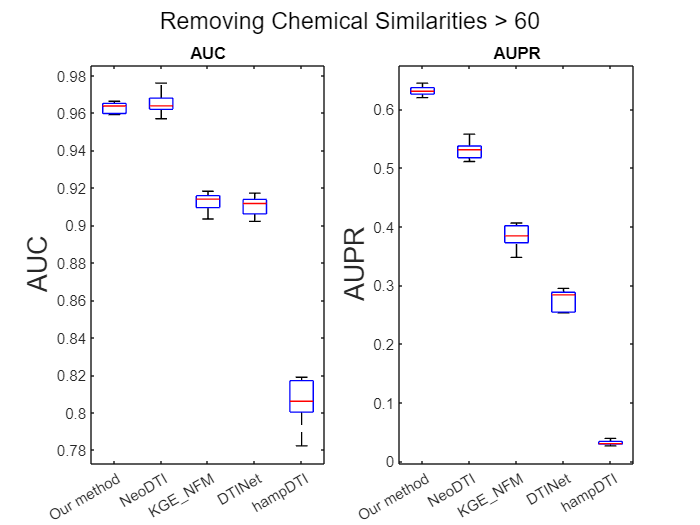

figure;
subplot(1,2,1);
boxplot([our_method_AUC NeoDTI_AUC DTINet_all_AUC KGE_NFM_AUC hampDTI_all_AUC]);
ylabel('AUC', 'FontSize', 16);
set(gca,'xticklabel',{'Our method','NeoDTI','KGE_NFM','DTINet','hampDTI'});
title('AUC');
%ylim([0.95 1]);

subplot(1,2,2);
boxplot([our_method_AUPR NeoDTI_AUPR DTINet_all_AUPR KGE_NFM_AUPR hampDTI_all_AUPR]);
%xlabel('Unalanced', 'FontSize', 16);
ylabel('AUPR', 'FontSize', 16);
set(gca,'xticklabel',{'Our method','NeoDTI','KGE_NFM','DTINet','hampDTI'});
title('AUPR');
sgtitle('Removing Chemical Similarities > 60');

Filter Target Similarity

Calculate the AUC and AUPR with AUCDownSample function.

targetSim = {protSeqSim};
targetTresh = {40};
for k = 1:10
    AUC_our_method = zeros(nfolds,1);
    AUPR_our_method = zeros(nfolds,1);
    AUC_NeoDTI = zeros(nfolds,1);
    AUPR_NeoDTI = zeros(nfolds,1);
    KGE_NFM_AUC = zeros(nfolds,1);
    KGE_NFM_AUPR = zeros(nfolds,1);
    DTINet_AUC = zeros(nfolds,1);
    DTINet_AUPR = zeros(nfolds,1);
    for j = 1:nfolds
        load(['../data/luo_dataset/warm_start_10_CVs/our_method/cv_' int2str(k) '/test' int2str(j) '.mat']);
        filteredTest = filterDTI(test_fold, {},targetSim,{},targetTresh,'target');
        [AUC_our_method(j), AUPR_our_method(j), ~,~,~,~] = AUCDownSample(filteredTest, our_method_predictions{k}{j});
        [AUC_NeoDTI(j), AUPR_NeoDTI(j), ~,~,~,~] = AUCDownSample(filteredTest, neoDTI_predictions{k}{j});
        [KGE_NFM_AUC(j), KGE_NFM_AUPR(j), ~,~,~,~] = AUCDownSample(filteredTest, KGE_NFM_predictions{k}{j});
        [DTINet_AUC(j), DTINet_AUPR(j), ~,~,~,~] = AUCDownSample(filteredTest, DTINet_predictions_10_1{k}{j});
        [hampDTI_AUC(j), hampDTI_AUPR(j), ~,~,~,~] = AUCDownSample(filteredTest, hampDTI_predictions{k}{j});
    end
    our_method_remove_drug_sim{k} = {AUC_our_method,AUPR_our_method};
    NeoDTI_remove_drug_sim{k} = {AUC_NeoDTI,AUPR_NeoDTI};
    KGE_NFM_remove_drug_sim{k} = {KGE_NFM_AUC,KGE_NFM_AUPR};
    DTINet_remove_drug_sim{k} = {DTINet_AUC,DTINet_AUPR};
    hampDTI_remove_drug_sim{k} = {hampDTI_AUC,hampDTI_AUPR};
end


nfolds = 10;
NeoDTI_AUC = zeros(nfolds,1);
NeoDTI_AUPR = zeros(nfolds,1);
our_method_AUC = zeros(nfolds,1);
our_method_AUPR = zeros(nfolds,1);
KGE_NFM_AUC = zeros(nfolds,1);
KGE_NFM_AUPR = zeros(nfolds,1);
DTINet_all_AUC = zeros(nfolds,1);
DTINet_all_AUPR = zeros(nfolds,1);
for j = 1:10
        NeoDTI_AUC(j) = mean(NeoDTI_remove_drug_sim{j}{1});
        NeoDTI_AUPR(j) = mean(NeoDTI_remove_drug_sim{j}{2});
        our_method_AUC(j) = mean(our_method_remove_drug_sim{j}{1});
        our_method_AUPR(j) = mean(our_method_remove_drug_sim{j}{2});
        KGE_NFM_AUC(j) = mean(KGE_NFM_remove_drug_sim{j}{1});
        KGE_NFM_AUPR(j) = mean(KGE_NFM_remove_drug_sim{j}{2});
        DTINet_all_AUC(j) = mean(DTINet_remove_drug_sim{j}{1});
        DTINet_all_AUPR(j) = mean(DTINet_remove_drug_sim{j}{2});
        hampDTI_all_AUC(j) = mean(hampDTI_remove_drug_sim{j}{1});
        hampDTI_all_AUPR(j) = mean(hampDTI_remove_drug_sim{j}{2});
end

mAUC = [our_method_AUC NeoDTI_AUC DTINet_all_AUC KGE_NFM_AUC hampDTI_AUC];
mAUPR = [our_method_AUPR NeoDTI_AUPR DTINet_all_AUPR KGE_NFM_AUPR hampDTI_AUPR];
%save("../../repository/paper_data/wm_seq_AUC.mat",'mAUC');
%save("../../repository/paper_data/wm_seq_AUPR.mat",'mAUPR');

Plot the AUC and AUPR values

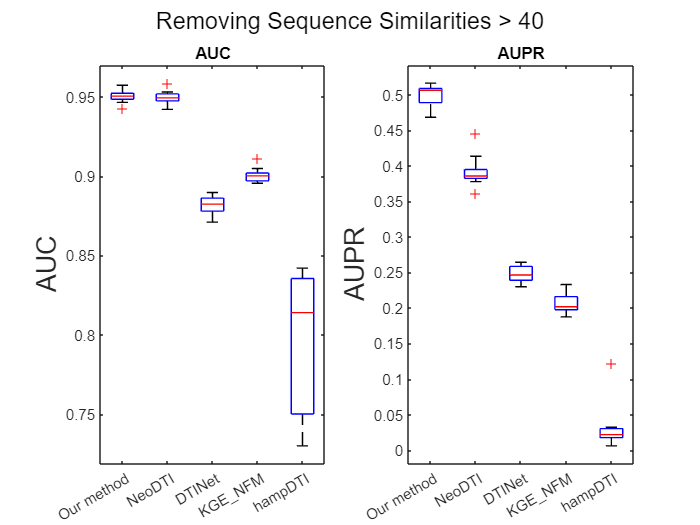

figure;
subplot(1,2,1);
boxplot([our_method_AUC NeoDTI_AUC DTINet_all_AUC KGE_NFM_AUC hampDTI_AUC]);
ylabel('AUC', 'FontSize', 16);
set(gca,'xticklabel',{'Our method','NeoDTI','DTINet','KGE_NFM','hampDTI'});
title('AUC');
%ylim([0.95 1]);

subplot(1,2,2);
boxplot([our_method_AUPR NeoDTI_AUPR DTINet_all_AUPR KGE_NFM_AUPR hampDTI_AUPR]);
%xlabel('Unalanced', 'FontSize', 16);
ylabel('AUPR', 'FontSize', 16);
set(gca,'xticklabel',{'Our method','NeoDTI','DTINet','KGE_NFM','hampDTI'});
title('AUPR');
sgtitle('Removing Sequence Similarities > 40');

Filter Chemical and Target Similarity

for k = 1:10
    AUC_our_method = zeros(nfolds,1);
    AUPR_our_method = zeros(nfolds,1);
    AUC_NeoDTI = zeros(nfolds,1);
    AUPR_NeoDTI = zeros(nfolds,1);
    KGE_NFM_AUC = zeros(nfolds,1);
    KGE_NFM_AUPR = zeros(nfolds,1);
    DTINet_AUC = zeros(nfolds,1);
    DTINet_AUPR = zeros(nfolds,1);
    for j = 1:nfolds
        load(['../data/luo_dataset/warm_start_10_CVs/our_method/cv_' int2str(k) '/test' int2str(j) '.mat']);
        filteredTest = filterDTI(test_fold, drugSim,targetSim,drugTresh,targetTresh,'both');
        [AUC_our_method(j), AUPR_our_method(j), ~,~,~,~] = AUCDownSample(filteredTest, our_method_predictions{k}{j});
        [AUC_NeoDTI(j), AUPR_NeoDTI(j), ~,~,~,~] = AUCDownSample(filteredTest, neoDTI_predictions{k}{j});
        [KGE_NFM_AUC(j), KGE_NFM_AUPR(j), ~,~,~,~] = AUCDownSample(filteredTest, KGE_NFM_predictions{k}{j});
        [DTINet_AUC(j), DTINet_AUPR(j), ~,~,~,~] = AUCDownSample(filteredTest, DTINet_predictions_10_1{k}{j});
        [hampDTI_AUC(j), hampDTI_AUPR(j), ~,~,~,~] = AUCDownSample(filteredTest, hampDTI_predictions{k}{j});
    end
    our_method_remove_drug_sim{k} = {AUC_our_method,AUPR_our_method};
    NeoDTI_remove_drug_sim{k} = {AUC_NeoDTI,AUPR_NeoDTI};
    KGE_NFM_remove_drug_sim{k} = {KGE_NFM_AUC,KGE_NFM_AUPR};
    DTINet_remove_drug_sim{k} = {DTINet_AUC,DTINet_AUPR};
    hampDTI_remove_drug_sim{k} = {hampDTI_AUC,hampDTI_AUPR};
end


nfolds = 10;
NeoDTI_AUC = zeros(nfolds,1);
NeoDTI_AUPR = zeros(nfolds,1);
our_method_AUC = zeros(nfolds,1);
our_method_AUPR = zeros(nfolds,1);
KGE_NFM_AUC = zeros(nfolds,1);
KGE_NFM_AUPR = zeros(nfolds,1);
DTINet_all_AUC = zeros(nfolds,1);
DTINet_all_AUPR = zeros(nfolds,1);
for j = 1:10
        NeoDTI_AUC(j) = mean(NeoDTI_remove_drug_sim{j}{1});
        NeoDTI_AUPR(j) = mean(NeoDTI_remove_drug_sim{j}{2});
        our_method_AUC(j) = mean(our_method_remove_drug_sim{j}{1});
        our_method_AUPR(j) = mean(our_method_remove_drug_sim{j}{2});
        KGE_NFM_AUC(j) = mean(KGE_NFM_remove_drug_sim{j}{1});
        KGE_NFM_AUPR(j) = mean(KGE_NFM_remove_drug_sim{j}{2});
        DTINet_all_AUC(j) = mean(DTINet_remove_drug_sim{j}{1});
        DTINet_all_AUPR(j) = mean(DTINet_remove_drug_sim{j}{2});
        hampDTI_all_AUC(j) = mean(hampDTI_remove_drug_sim{j}{1});
        hampDTI_all_AUPR(j) = mean(hampDTI_remove_drug_sim{j}{2});
end

mAUC = [our_method_AUC NeoDTI_AUC DTINet_all_AUC KGE_NFM_AUC hampDTI_AUC];
mAUPR = [our_method_AUPR NeoDTI_AUPR DTINet_all_AUPR KGE_NFM_AUPR hampDTI_AUPR];
%save("../../repository/paper_data/wm_both_AUC.mat",'mAUC');
%save("../../repository/paper_data/wm_both_AUPR.mat",'mAUPR');

Plot the AUC and AUPR values

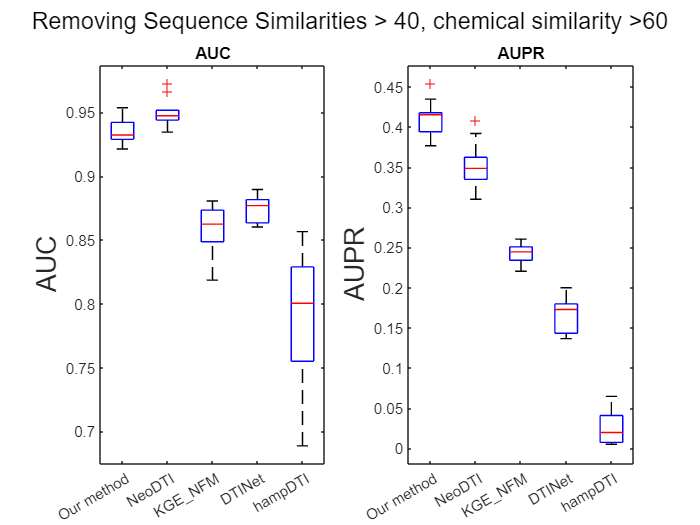

figure;
subplot(1,2,1);
boxplot([our_method_AUC NeoDTI_AUC DTINet_all_AUC KGE_NFM_AUC hampDTI_AUC]);
ylabel('AUC', 'FontSize', 16);
set(gca,'xticklabel',{'Our method','NeoDTI','KGE_NFM','DTINet','hampDTI'});
title('AUC');
%ylim([0.95 1]);

subplot(1,2,2);
boxplot([our_method_AUPR NeoDTI_AUPR DTINet_all_AUPR KGE_NFM_AUPR hampDTI_AUPR]);
%xlabel('Unalanced', 'FontSize', 16);
ylabel('AUPR', 'FontSize', 16);
set(gca,'xticklabel',{'Our method','NeoDTI','KGE_NFM','DTINet','hampDTI'});
title('AUPR');
sgtitle('Removing Sequence Similarities > 40, chemical similarity >60');